# eventospie_carrera

Detección de eventos en la carrera

## Syntax

`[IC,FC]=eventospie_carrera(gyr,th,freq)`

`[IC,FC,MaxS,MinS,MVP,MP]=eventospie_carrera(gyr,th,freq,gyrx)` 

## Description

`[``IC,FC``]=eventospie_carrera(``gyr,th,freq``)`  tomando como entrada la velocidad angular en el eje mediolateral `gyr`, muestreada a cierta frecuencia `freq`, y tras realizar un proceso interno de filtrado (apoyado en filtro0 de la SP-TB) con una frecuencia de corte `th`, se identifican los eventos de contacto inicial IC y final FC del pie en el que esta el sensor. 

`[``IC,FC,MaxS,MinS,MVP,MP``]=eventospie_carrera(``gyr,th,freq, gyrx``) `es la versión completa, que añade otras 4 detecciones, y requiere como entrada el giróscopio en la dirección antero-posterior `gyrx`. 

Los eventos se describen en: Athletic and sport issues in musculoskeletal rehabilitation, David J_ Magee; James E_ Zachazewski; William S_ Quillen; Ed. Elsevier Inc, Health, 2011. 

La siguiente es una gráfica adaptada del libro (Fig. 18-1) con anotaciones: 

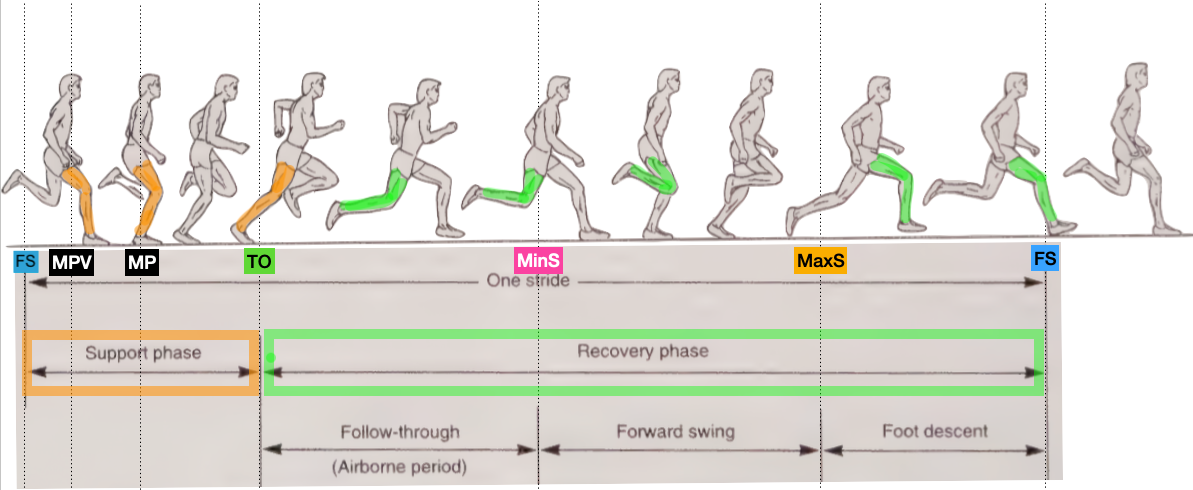

La fase de soporte suele tener duraciones del 30-40% del ciclo.

- FS (FootStrike): The moment the foot first contacts the ground, initiating the stance phase.

- MPV (Maximum Pronation Velocity): The point at which the foot undergoes the fastest rate of pronation (inward roll of the foot).

- MP (Maximum Pronation): The point where the foot reaches its maximum inward roll during the stance phase.  

- TO (ToeOff): The moment the foot leaves the ground, ending the stance phase and starting the swing phase.

- Min Swing (Maximum Backward Swing): the point in the gait cycle where the swinging leg reaches its furthest backward position.

- Max Swing (Maximum Forward Swing): the point in the gait cycle where the swinging leg reaches its furthest forward position.

## Examples

Suponemos que tenemos una señal de giro ML disponible obtenida con un sensor a 120Hz:

%% Parámetros de simulación
freq = 200;          % Frecuencia de muestreo [Hz]
t = 0:1/freq:5;      % 5 segundos de señal
th = 150;            % Umbral para detección [°/s]

% -------------------------------------------------------------------------
% Generación de una señal sintética tipo carrera
% -------------------------------------------------------------------------
% Señal oscilatoria con picos que simulan el swing del pie
gyr_ml = 200 * sin(2*pi*2*t) + 50*randn(size(t));    % eje mediolateral
gyr_fr = 100 * sin(2*pi*2*t + pi/4);                 % eje frontal (para pronación)

% Introducir pequeñas variaciones para simular ciclos reales
gyr_ml = gyr_ml .* (1 + 0.1*sin(0.5*pi*t));


## Argumentos de entrada

%    gyr           - vector con la velocidad de giro en el eje mediolateral
%    th            - velocidad mínima a alcanzar para detectar eventos. Aconsejado 150
%    frecuencia    - frecuencia de muestreo.
%    gyrx           - vector con la velocidad de giro en el eje antero-posterior

[ic, fc, max_s, min_s, mvp, mp] = eventos_pie_carrera(gyr_ml, th, freq, gyr_fr);


## Argumentos de salida

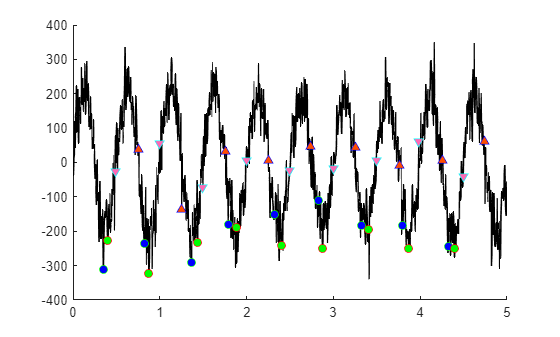

%    IC : muestra en las que se ha detectado el contacto inicial con el suelo
%    FC : muestra en las que se ha detectado el final del contacto con el suelo
%    Max Swing (MaxS)   
%    Min Swing (MinS)
%    Pronation Velocity (MPV)
%    Max. Pronation (MP)


% ==================== REPRESENTACIÓN DE EVENTOS ====================
figure
hold on
plot(t, gyr_ml, 'k', 'LineWidth', 1.2, 'DisplayName', 'Velocidad angular mediolateral')

% Eventos principales
if ~isempty(ic),  plot(t(ic),  gyr_ml(ic),  'go', 'MarkerFaceColor','b', 'DisplayName','IC (FS)'); end
if ~isempty(fc),  plot(t(fc),  gyr_ml(fc),  'ro', 'MarkerFaceColor','g', 'DisplayName','FC (TO)'); end
if ~isempty(max_s),plot(t(max_s),gyr_ml(max_s),'b^', 'MarkerFaceColor','#ff4d00', 'DisplayName','Max Swing'); end
if ~isempty(min_s),plot(t(min_s),gyr_ml(min_s),'cv', 'MarkerFaceColor','#ff69b4', 'DisplayName','Min Swing'); end
if ~isempty(mvp), plot(t(mvp), gyr_ml(mvp), 'ms', 'MarkerFaceColor','black', 'DisplayName','MVP (Máx. vel. pronación)'); end

if ~isempty(mp),  plot(t(mp),  gyr_ml(mp),  'kd', 'MarkerFaceColor','black', 'DisplayName','MP (Máx. pronación)'); end

Array indices must be positive integers or logical values.


% Configuración del gráfico
xlabel('Tiempo [s]')
ylabel('Velocidad angular mediolateral [°/s]')
title('Detección automática de eventos del pie durante la carrera')
legend('show', 'Location','northoutside', 'Orientation','horizontal')
grid on
ylim([-300 300])
xlim([0 5])
set(gca, 'FontSize', 11)
hold off

